wing_length = [10.4, 10.8, 11.1, 10.2, 10.3, 10.2, 10.7, 10.5, 10.8, 11.2, 10.6, 11.4]

wing_length =    10.4000   10.8000   11.1000   10.2000   10.3000   10.2000   10.7000   10.5000   10.8000   11.2000   10.6000   11.4000


tail_length = [7.4, 7.6, 7.9, 7.2, 7.4, 7.1, 7.4, 7.2, 7.8, 7.7, 7.8, 8.3]

tail_length =     7.4000    7.6000    7.9000    7.2000    7.4000    7.1000    7.4000    7.2000    7.8000    7.7000    7.8000    8.3000


ave_wing_length = mean(wing_length)

ave_wing_length = 10.6833

ave_tail_length = mean(tail_length)

ave_tail_length = 7.5667

std_wing_length = std(wing_length)

std_wing_length = 0.3950

std_tail_length = std(tail_length)

std_tail_length = 0.3499

n = length(wing_length)

n = 12

sample_ave_wing_length = mean(normrnd(ave_wing_length, std_wing_length,n))

sample_ave_wing_length =    10.7327   10.6121   10.7590   10.5268   10.8319   10.4779   10.7728   10.6700   10.4761   10.6598   10.8147   10.4908


sample_ave_tail_length = mean(normrnd(ave_tail_length, std_tail_length,n))

sample_ave_tail_length =     7.4489    7.7861    7.4402    7.5444    7.7116    7.7353    7.5326    7.5803    7.4377    7.5112    7.5192    7.5130


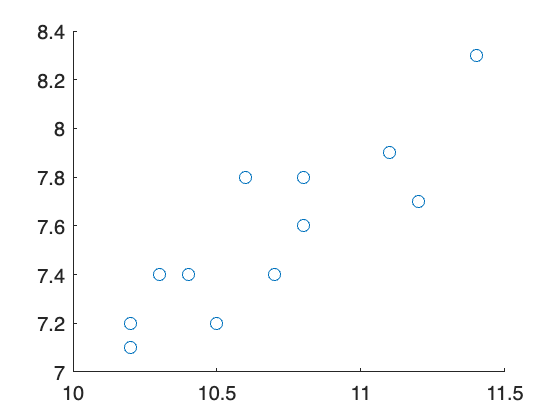

%1.
scatter(wing_length, tail_length)

%2.
%clearly incorrect formula but dk how to fix it
r_computed = (ave_wing_length-sample_ave_wing_length).*(ave_tail_length-sample_ave_tail_length)/(sqrt(ave_wing_length-sample_ave_wing_length).^2)*(sqrt(ave_tail_length-sample_ave_tail_length).^2)

r_computed =    -0.0007    0.0013   -0.0007   -0.0001    0.0009    0.0010   -0.0002    0.0001   -0.0008   -0.0003   -0.0003   -0.0003



r = corrcoef(wing_length, tail_length)

r =     1.0000    0.8704
    0.8704    1.0000



%3. standard error
st_error = sqrt(1-r^2)/(n-2)

st_error =    0.0000 + 0.0870i   0.0000 + 0.0861i
   0.0000 + 0.0861i   0.0000 + 0.0870i


z_criterion = -norminv((0.95)/2)

z_criterion = 0.0627

%confidence intervals 
%fishers z transform 
z = 0.5*log((1+r)/(1-r))

z =     1.3345    1.3680
    1.3680    1.3345



%std
std_z = sqrt(1/(n-3))

std_z = 0.3333

z_r = z + z_criterion * st_error

z_r =    1.3345 + 0.0055i   1.3680 + 0.0054i
   1.3680 + 0.0054i   1.3345 + 0.0055i




e = exp(1);
e_exp = e^2*z;
r_corrected = (e_exp-1)/(e_exp+1)

r_corrected =     0.9090   -0.0910
   -0.0910    0.9090


%4. 

ans =    11.2925   11.4011   11.1626   11.4285   11.2500   11.2730   11.3527   11.2623   11.3579   11.3243   11.3424   11.2121


%yes

%5. 
%hypothesis testing- this is very wrong and I am very stuck...
t = r_corrected/st_error

t = 1.0e+02 *

   0.0000 - 5.1730i   0.0000 + 5.1257i
   0.0000 + 5.1257i   0.0000 - 5.1730i



h_null_teststat = (z_r)-(z_rs)/(sqrt(1/(n-3)))

h_null_teststat =   -2.6691 - 0.0109i  -2.7361 - 0.0108i
  -2.7361 - 0.0108i  -2.6691 - 0.0109i
